open_system('task_4_sim');
set_param('task_4_sim/xh_', 'VariableName', 'xh_')
set_param('task_4_sim/xx', 'VariableName', 'xx')
set_param('task_4_sim/e', 'VariableName', 'e')
set_param('task_4_sim/u', 'VariableName', 'u')
set_param('task_4_sim/zh_', 'VariableName', 'zh_')

out = sim('task_4_sim');

Found algebraic loop containing: 
task_4_sim/Product11 (algebraic variable)
task_4_sim/Product2
task_4_sim/Add1
task_4_sim/Add5
task_4_sim/Matrix Concatenate1
task_4_sim/Product10
task_4_sim/Product3 (algebraic variable)


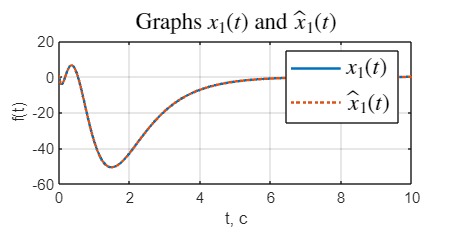


figure('Position', [100 100 800 400])
%plot(out.xx.Time, out.xx.Data(:,1),'-', 'LineWidth',1.5)
plot(out.xx.Time, out.xx.Data(1,:),'-', 'LineWidth',1.5)
hold on
plot(out.xh_.Time, out.xh_.Data(1, :),':', 'LineWidth',1.5)
%plot(out.x_,'-', 'LineWidth',1.5)
%plot(out.y3,'-.', 'LineWidth',1.5)

grid()
title('Graphs $x_1(t)$ and $\hat{x}_1(t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$x_1(t)$', '$\hat{x}_1(t)$', 'Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')
%yticks([0 1 2 3 4 5 6 7 8 9 10 11 12 13 14])
hold off

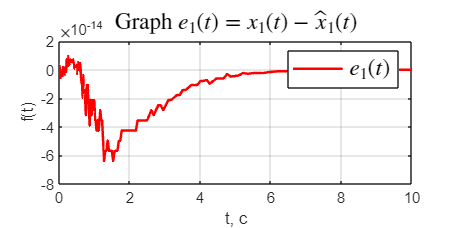


plot(out.e.Time, out.e.Data(1, :),'r', 'LineWidth', 1.5)

grid("on")
title('Graph $e_1(t)=x_1(t) - \hat{x}_1 (t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$e_1(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')

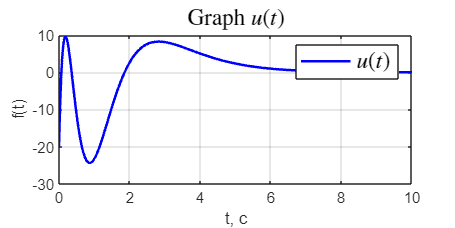

%ylim([-7 1])
%hold off


plot(out.u,'b', 'LineWidth', 1.5)
%hold on

grid("on")
title('Graph $u(t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$u(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')

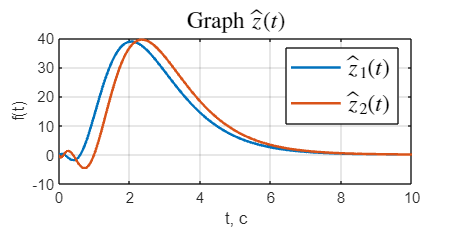



plot(out.zh_, 'LineWidth', 1.5)
%hold on

grid("on")
title('Graph $\hat{z}(t)$', 'Interpreter','latex',  'FontSize', 14)
legend('$\hat{z}_1(t)$', '$\hat{z}_2(t)$','Interpreter','latex',  'FontSize', 14)
ylabel('f(t)')
xlabel('t, с')